# **Brain-behaviour relationships in the tbfMRI choir-singing dataset: clinical outcomes**

The results from the behavioural analyses are:

- Communication index 

- Responsive Speech

clear all
% Specify directories and patients
data_path='/Volumes/LASA/Aphasia_project/tb-fMRI/results/post-pre_diff_images/TU/';
data_path2='/Volumes/LASA/Aphasia_project/tb-fMRI/results/post-pre_diff_images/TU_TP12/';
mask_path='/Volumes/LASA/Aphasia_project/tb-fMRI/results/';
code_path='/Volumes/LASA/Aphasia_project/manuscripts/fMRI_SciRep/code/brainbeh/';
addpath(code_path) %add code path

First, we will extract the values from the significant behavioural variables for each patient:

% Import behavioural data and extract variables for the fMRI sample (N=28)
importfile_behaviour('LASA_questionnaires_CVA_TBI_beh_fMRI.csv');
Comm_Idx_int_all=ans.Communication_index_INT;
Resp_Speech_Idx_int_all=ans.Change_WAB_naming_repetition_intervention;
Comm_Idx_21_all=ans.Communication_index_P_21;
Resp_Speech_Idx_21_all=ans.Change_WAB_naming_repetition_21;
ID_BIDS_all=ans.ID_num;

% Save contrast name to variable
contrast1='Sing_along>Baseline';
mask1name='singavsrest_trainedvsuntrained_cluster_bin.nii';
mask2name='AB>BAxTP2>TP1_FWEc_cluster_bin.nii';


## Contrast 1: Paired T test Tydyy-Uulaa Sing along vs Rest

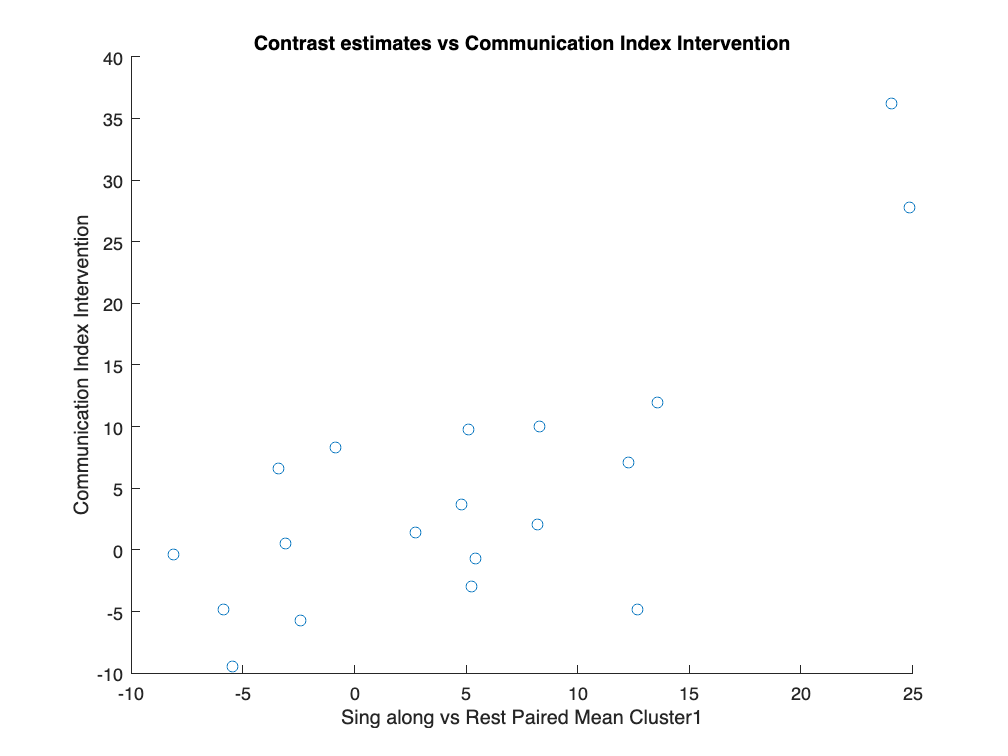

% Get the image filenames
filenames_contrast1= dir(fullfile(data_path,contrast1));
filenames_contrast1(ismember({filenames_contrast1.name},{'.','..'}))=[];

% Get L2 mask indices from FWEc cluster
    mask1=spm_vol(fullfile(mask_path,'paired T test/singa_vs_rest_TrainedvsUntrained_Age_TIV_wo_motion_outliers_wo_14_expmaskBRAVE/',mask1name)); %created manually with SPM L2 results
    [M, XYZmm]=spm_read_vols(mask1);
    mask1_idx=find(M~=0);
    mask1_int=mean(M(mask1_idx));%internal check
    
% Get mean cluster intensity for all patients
for i=1:size(filenames_contrast1,1)
    V=spm_vol(fullfile(data_path,contrast1,filenames_contrast1(i).name)); % Get image information
    [Y, XYZmm]=spm_read_vols(V);
    mean_int=mean(Y(mask1_idx));
    [~,name,ext] =fileparts(filenames_contrast1(i).name);
    pa_int_mask1{i,1}=str2num(name(end-1:end)); %Save the patient ID in BIDS
    pa_int_mask1{i,2}=mean_int;% Save mean intensity value for the cluster from all patients
end

%% Get behavioural values from the patients with existing images
ID_BIDS_pat=cell2mat(pa_int_mask1(:,1));
[idx_pat,iall,i] = intersect(ID_BIDS_all,ID_BIDS_pat);
Comm_Idx_int_pat_contrast1=Comm_Idx_int_all(iall,:);
Resp_Speech_Idx_int_pat_contrast1=Resp_Speech_Idx_int_all(iall,:);

%%%%COMMUNICATION INDEX%%%%
% Remove patients with NaN values in behaviour
if sum(isnan(Comm_Idx_int_pat_contrast1(:,1)))~=0
    NAN_Index_contrast1=find(isnan(Comm_Idx_int_pat_contrast1(:,1)));
    Comm_Idx_int_pat_contrast1(NAN_Index_contrast1,:)=[];
    pa_int_mask1_comm=cell2mat(pa_int_mask1(:,2));
    pa_int_mask1_comm(NAN_Index_contrast1,:)=[];
end
%% Plot Intensity against behaviour for the cluster mean
for p=1:size(1,1)
        y=Comm_Idx_int_pat_contrast1;
        if exist('pa_int_mask1_comm')==1
            x=pa_int_mask1_comm;
        else
            x=cell2mat(pa_int_mask1(:,2));
        end
        figure
        scatter(x,y)
        title ('Contrast estimates vs Communication Index Intervention'), xlabel(['Sing along vs Rest Paired Mean Cluster' num2str(p)]), ylabel ('Communication Index Intervention')
        cd(fullfile(code_path,'outputs','clinical'))
        saveas(gcf,['scatter_betas_PairedT_SingavsRest_Communication_Index_mean_cluster' num2str(p) '.jpg'])
        save('Communication_Index_singavsrest_pairedT_mean_cluster','x','y')
        CI_singavsrest_T=table(x,y);
        writetable(CI_singavsrest_T, 'CI_singavsrest_pairedT_mean_cluster.xlsx')
end

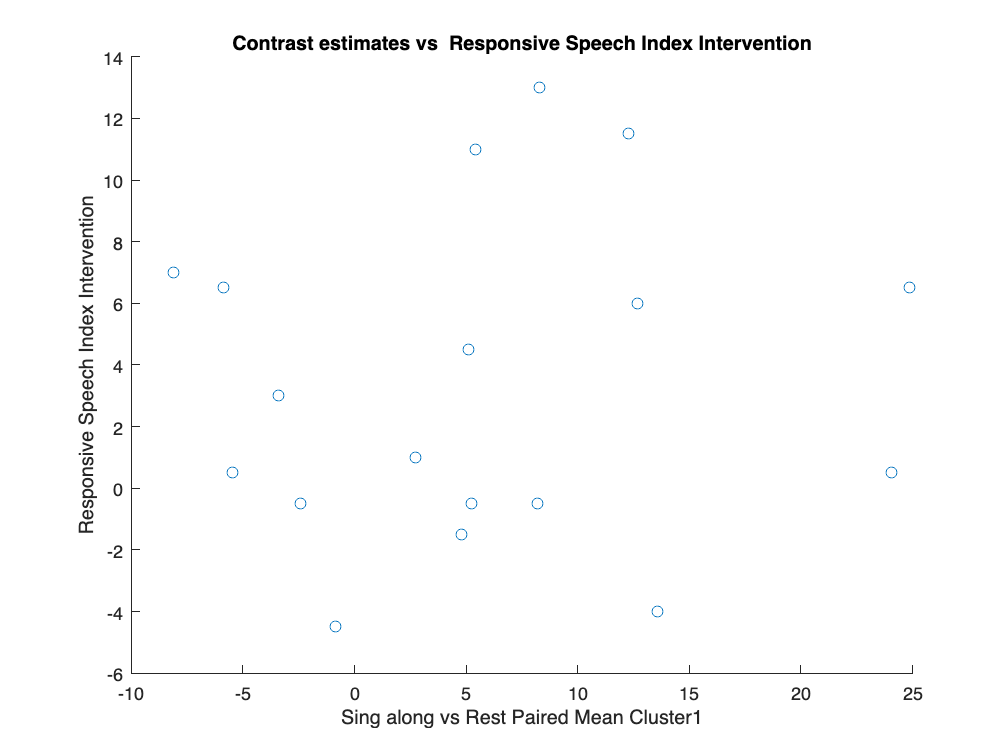


% correlation
[rho_mask1,pval_mask1] = corr(x,y,'Type','Pearson');
save('CI_Pearson_singavsrest_pairedT_mean_cluster','rho_mask1','pval_mask1')

[rho_mask1,pval_mask1] = corr(x,y,'Type','Spearman');
clear x y M mean_int Y V NAN_Index_contrast1

%%%%RESPONSIVE SPEECH INDEX%%%%
% Remove patients with NaN values in behaviour
if sum(isnan(Resp_Speech_Idx_int_pat_contrast1(:,1)))~=0
    NAN_Index_contrast1=find(isnan(Resp_Speech_Idx_int_pat_contrast1(:,1)));
    Resp_Speech_Idx_int_pat_contrast1(NAN_Index_contrast1,:)=[];
    pa_int_mask1_resp=cell2mat(pa_int_mask1(:,2));
    pa_int_mask1_resp(NAN_Index_contrast1,:)=[];
end
%% Plot Intensity against behaviour for the cluster mean
for p=1:size(mask1,1)
        y=Resp_Speech_Idx_int_pat_contrast1;
           if exist('pa_int_mask1_resp')==1
            x=pa_int_mask1_resp;
        else
            x=cell2mat(pa_int_mask1(:,2));
           end
        figure
        scatter(x,y)
        title ('Contrast estimates vs  Responsive Speech Index Intervention'), xlabel(['Sing along vs Rest Paired Mean Cluster' num2str(p)]), ylabel ('Responsive Speech Index Intervention')
        cd(fullfile(code_path,'outputs','clinical'))
        saveas(gcf,['scatter_betas_PairedT_SingavsRest_Responsive_Speech_Index_mean_cluster' num2str(p) '.jpg'])
        save('Responsive_Speech_Index_int_singavsrest_pairedT_mean_cluster','x','y')
        RSI_singavsrest_T=table(x,y);
        writetable(RSI_singavsrest_T, 'RSI_singavsrest_pairedT_mean_cluster.xlsx')
end


% correlation
[rho_mask1,pval_mask1] = corr(x,y,'Type','Pearson');
save('RSI_Pearson_singavsrest_pairedT_mean_cluster','rho_mask1','pval_mask1')
[rho_mask1,pval_mask1] = corr(x,y,'Type','Spearman');
clear x y M mean_int Y V


## Contrast 1: Flexible AB>BAxTP2>TP1 Tydyy-Uulaa Sing along vs Rest

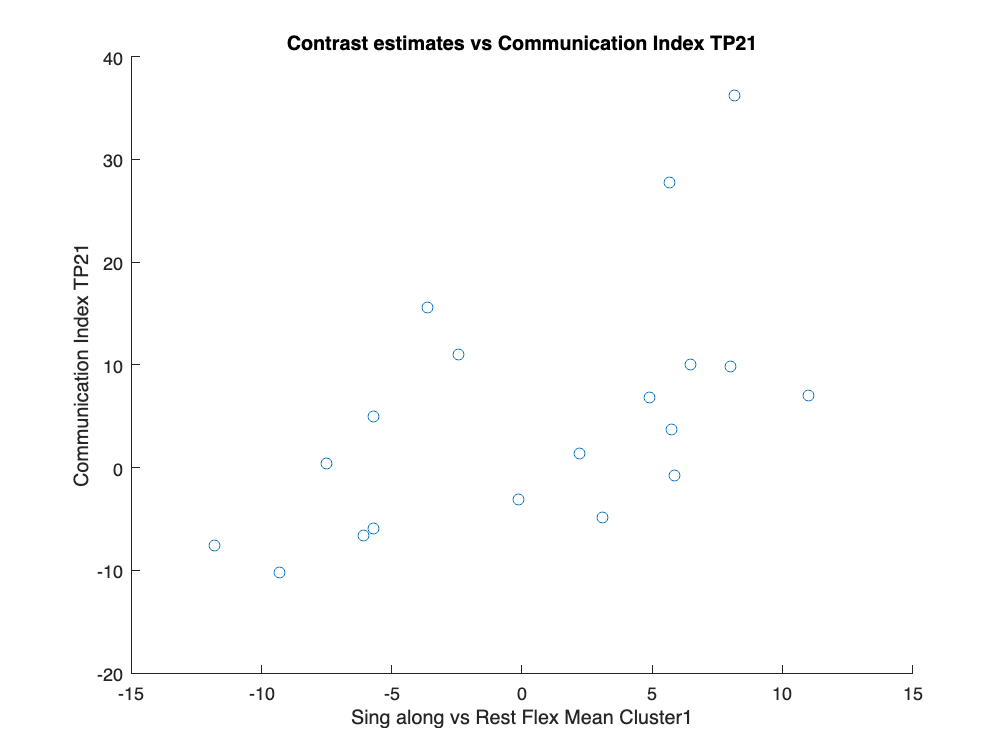

% Get the image filenames
filenames_contrast1f= dir(fullfile(data_path2,contrast1));
filenames_contrast1f(ismember({filenames_contrast1f.name},{'.','..'}))=[];
% Get L2 mask indices from FWEc cluster
    mask2=spm_vol(fullfile(mask_path,'flexible factorial/singa_vs_rest_TU_2by2_Age_TIV_WABAQ_expmaskBRAVE/',mask2name)); %created manually with SPM L2 results
    [M, XYZmm]=spm_read_vols(mask2);
    mask2_idx=find(M~=0);
    mask2_int=mean(M(mask2_idx));%internal check
    
% Get mean cluster intensity for all patients
for i=1:size(filenames_contrast1f,1)
    V=spm_vol(fullfile(data_path2,contrast1,filenames_contrast1f(i).name)); % Get image information
    [Y, XYZmm]=spm_read_vols(V);
    mean_int=mean(Y(mask2_idx));
    [~,name,ext] =fileparts(filenames_contrast1f(i).name);
    pa_21_mask2{i,1}=str2num(name(end-1:end)); %Save the patient ID in BIDS
    pa_21_mask2{i,2}=mean_int;% Save mean intensity value for the cluster from all patients
end

%% Get behavioural values from the patients with existing images
ID_BIDS_pat=cell2mat(pa_21_mask2(:,1));
[idx_pat,iall,i] = intersect(ID_BIDS_all,ID_BIDS_pat);
Comm_Idx_21_pat_contrast1f=Comm_Idx_21_all(iall,:);
Resp_Speech_Idx_21_pat_contrast1f=Resp_Speech_Idx_21_all(iall,:);

%%%% COMMUNICATION INDEX %%%%
% Remove patients with NaN values in behaviour
if sum(isnan(Comm_Idx_21_pat_contrast1f(:,1)))~=0
    NAN_Index_contrast1f=find(isnan(Comm_Idx_21_pat_contrast1f(:,1)));
    Comm_Idx_21_pat_contrast1f(NAN_Index_contrast1f,:)=[];
    pa_21_mask2_comm=cell2mat(pa_21_mask2(:,2));
    pa_21_mask2_comm(NAN_Index_contrast1f,:)=[];
end
    
%% Plot Intensity against behaviour for the cluster mean
for p=1:size(1,1)
        y=Comm_Idx_21_pat_contrast1f;
           if exist('pa_21_mask2_comm')==1
            x=pa_21_mask2_comm;
        else
            x=cell2mat(pa_21_mask2(:,2));
           end
        figure
        scatter(x,y)
        title ('Contrast estimates vs Communication Index TP21'), xlabel(['Sing along vs Rest Flex Mean Cluster' num2str(p)]), ylabel ('Communication Index TP21')
        cd(fullfile(code_path,'outputs','clinical'))
        saveas(gcf,['scatter_betas_flex_SingavsRest_Communication_Index_mean_cluster' num2str(p) '.jpg'])
        save('Communication_Index_21_singavsrest_flex_mean_cluster','x','y')
        CI_singavsrest_F=table(x,y);
        writetable(CI_singavsrest_F, 'CI_singavsrest_F_mean_cluster.xlsx');
end


% correlation
[rho_mask2,pval_mask2] = corr(x,y,'Type','Pearson');
save('CI_Pearson_singavsrest_flex_mean_cluster','rho_mask1','pval_mask1')
[rho_mask2,pval_mask2] = corr(x,y,'Type','Spearman')

rho_mask2 = 0.6228

pval_mask2 = 0.0053

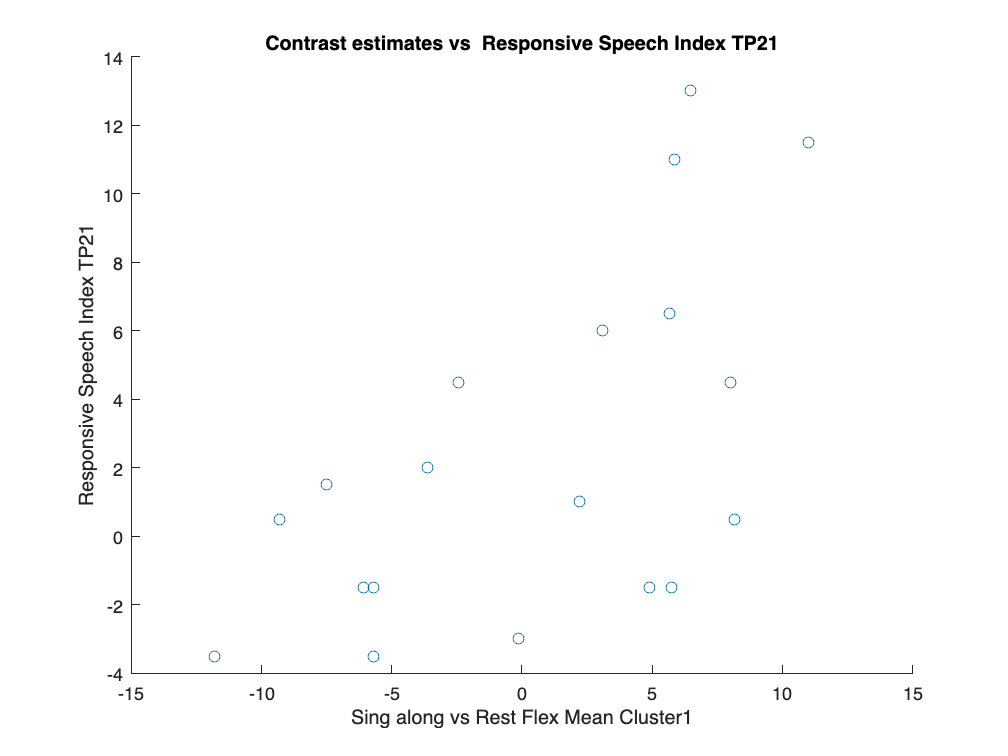

clear x y M mean_int Y V

%%%% RESPONSIVE SPEECH INDEX %%%%
% Remove patients with NaN values in behaviour
if sum(isnan(Resp_Speech_Idx_21_pat_contrast1f(:,1)))~=0
    NAN_Index_contrast1f=find(isnan(Resp_Speech_Idx_21_pat_contrast1f(:,1)));
    Resp_Speech_Idx_21_pat_contrast1f(NAN_Index_contrast1f,:)=[];
    pa_21_mask2_resp=cell2mat(pa_21_mask2(:,2));
    pa_21_mask2_resp(NAN_Index_contrast1f,:)=[];
end

%% Plot Intensity against behaviour for the cluster mean
for p=1:size(1,1)
        y=Resp_Speech_Idx_21_pat_contrast1f;
           if exist('pa_21_mask2_resp')==1
            x=pa_21_mask2_resp;
        else
            x=cell2mat(pa_21_mask2(:,2));
           end
        figure
        scatter(x,y)
        title ('Contrast estimates vs  Responsive Speech Index TP21'), xlabel(['Sing along vs Rest Flex Mean Cluster' num2str(p)]), ylabel ('Responsive Speech Index TP21')
        cd(fullfile(code_path,'outputs','clinical'))
        saveas(gcf,['scatter_betas_flex_SingavsRest_Responsive_Speech_Index_mean_cluster' num2str(p) '.jpg'])
        save('Responsive_Speech_Index_21_singavsrest_flex_mean_cluster','x','y')
        RSI_singavsrest_F=table(x,y);
        writetable(RSI_singavsrest_F, 'RSI_singavsrest_F_mean_cluster.xlsx')
end


% correlation
[rho_mask2,pval_mask2] = corr(x,y,'Type','Pearson');
save('RSI_Pearson_singavsrest_flex_mean_cluster','rho_mask1','pval_mask1')
[rho_mask2,pval_mask2] = corr(x,y,'Type','Spearman')

rho_mask2 = 0.5653

pval_mask2 = 0.0117

clear x y M mean_int Y V
